# Honours Live Script 11

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarHonours", 'var')
     clearVarsArray = clearVars();
     clear(clearVarsArray{:})
     clear clearVarsArray
     save matlabHonours.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Data Analysis of Connectivity - Mean and Variance

Data Analysis of Connectivity - Autocorrelation

Data Analysis of Connectivity - Correlation

Data Analysis Main Text Figure - Coral Trout

Solution Characteristics

3 Reef Analytical Model Optimisation Space

## Assumptions Made

## Notes

namesVecHawaii

namesVecHawaii = 1×60 string array
    "hi_june_1993_norm.mat"    "hi_july_1993_norm.mat"    "hi_august_1993_norm.mat"    "hi_june_1994_norm.mat"    "hi_july_1994_norm.mat"    "hi_august_1994_norm.mat"    "hi_june_1995_norm.mat"    "hi_july_1995_norm.mat"    "hi_august_1995_norm.mat"    "hi_june_1996_norm.mat"    "hi_july_1996_norm.mat"    "hi_august_1996_norm.mat"    "hi_june_1997_norm.mat"    "hi_july_1997_norm.mat"    "hi_august_1997_norm.mat"    "hi_june_1998_norm.mat"    "hi_july_1998_norm.mat"    "hi_august_1998_norm.mat"    "hi_june_1999_norm.mat"    "hi_july_1999_norm.mat"    "hi_august_1999_norm.mat"    "hi_june_2000_norm.mat"    "hi_july_2000_norm.mat"    "hi_august_2000_norm.mat"    "hi_june_2001_norm.mat"    "hi_july_2001_norm.mat"    "hi_august_2001_norm.mat"    "hi_june_2002_norm.mat"    "hi_july_2002_norm.mat"    "hi_august_2002_norm.mat"    "hi_june_2003_norm.mat"    "hi_july_2003_norm.mat"    "hi_august_2003_norm.mat"    "hi_june_2004_norm.mat"    "hi_july_2004_norm.ma

## Data Analysis of Connectivity - Mean and Variance

% I know I have code that use to do this so I will go and find it hehe
% create some interesting statistics
totalConnCT = length(conMatsCT{1})^2

totalConnCT = 3621409

var1 = zeros(nReefsCT, nReefsCT);
for i = 1:nMatsCT
    var1 = var1 + conMatsCT{i};
end
zeroConnCT = sum(var1 == 0, "all")

zeroConnCT = 2993934

nonzeroConnCT = sum(var1 > 0, "all")

nonzeroConnCT = 627475

nonzeroConnCT + zeroConnCT == totalConnCT

ans = logical
   1


nonzeroConnCT / totalConnCT

ans = 0.1733

% check what that spike shit is
var1 = zeros(30, 1);
var1(1) = 0.021;
var2 = mean(var1);
var3 = std(var1);
var3 / var2

ans = 5.4772

% for now, let's determine the connections which have at least one nonzero
% value
[meanConnCT, stdConnCT, minMaxConnCT, ~] = connectivityAnalysis( ...
    conMatsCT, eps);

% repeat the same analysis for the SLIM model outputs for COTS
[meanConnSLIM, stdConnSLIM, minMaxConnSLIM, ~] = ...
    connectivityAnalysis(conMatsSLIM, eps);

% repeat the same analysis for the GBRLUp model outputs for COTS
[meanConnGBRLUp, stdConnGBRLUp, minMaxConnGBRLUp, ~] = ...
    connectivityAnalysis(conMatsGBRLUp, eps);

% repeat the same analysis for the GBRLMd model outputs for COTS
[meanConnGBRLMd, stdConnGBRLMd, minMaxConnGBRLMd, ~] = connectivityAnalysis( ...
    conMatsGBRLMd, eps);

% repeat the same analysis for the GBRLDp model outputs for COTS
[meanConnGBRLDp, stdConnGBRLDp, minMaxConnGBRLDp, ~] = connectivityAnalysis( ...
    conMatsGBRLDp, eps);

% just for something new and different, repeat the analysis for the Hawaii
% data
[meanConnHaw, stdConnHaw, minMaxConnHaw, ~] = connectivityAnalysis( ...
    conMatsHawaii, eps);

% let's see if I can do this in tabular form too, because that would be
% cool, maybe could colorcode shit but also I'm not entirely sure if that's
% a good ideas
conAnalysisColNames = ["Coral Trout", "Coral", "COTS (SLIM)", ...
    "COTS (GBRLUp)", "COTS (GBRLMd)", "COTS (GBRLDp)"]

conAnalysisColNames = 1×6 string array
    "Coral Trout"    "Coral"    "COTS (SLIM)"    "COTS (GBRLUp)"    "COTS (GBRLMd)"    "COTS (GBRLDp)"


% [conAnTable, conAnRowNames] = connectivityAnalysisMult({conMatsCT, ...
%     conMatsSLIM, conMatsGBRLUp, conMatsGBRLMd, conMatsGBRLDp})

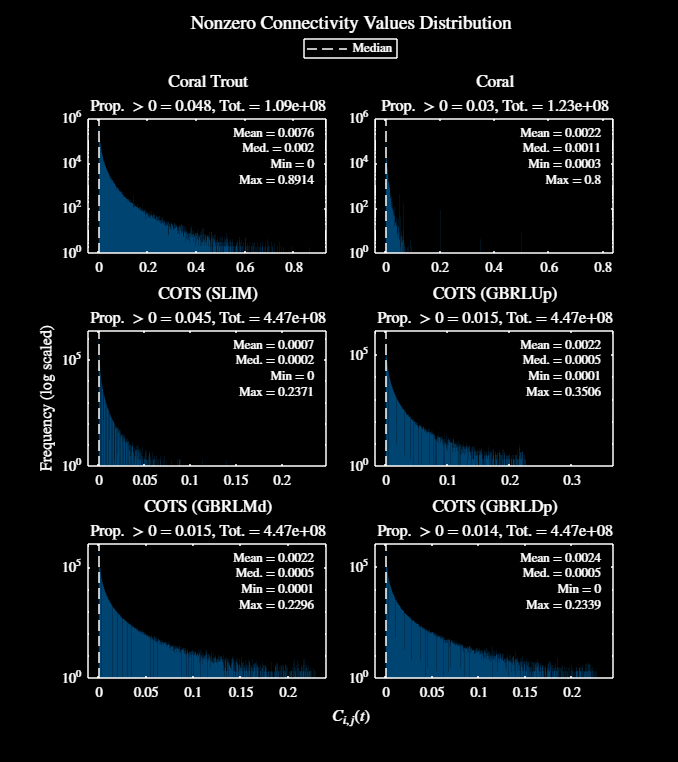

% let's also plot the distribution of the connectivity values (nonzero
% only)
figure
plotConnectivityDist({conMatsCT, conMatsHawaii, conMatsSLIM, ...
    conMatsGBRLUp, conMatsGBRLMd, conMatsGBRLDp}, conAnalysisColNames)
setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityDistribution")
darkFig()
saveFig("connectivityDistributionDM")

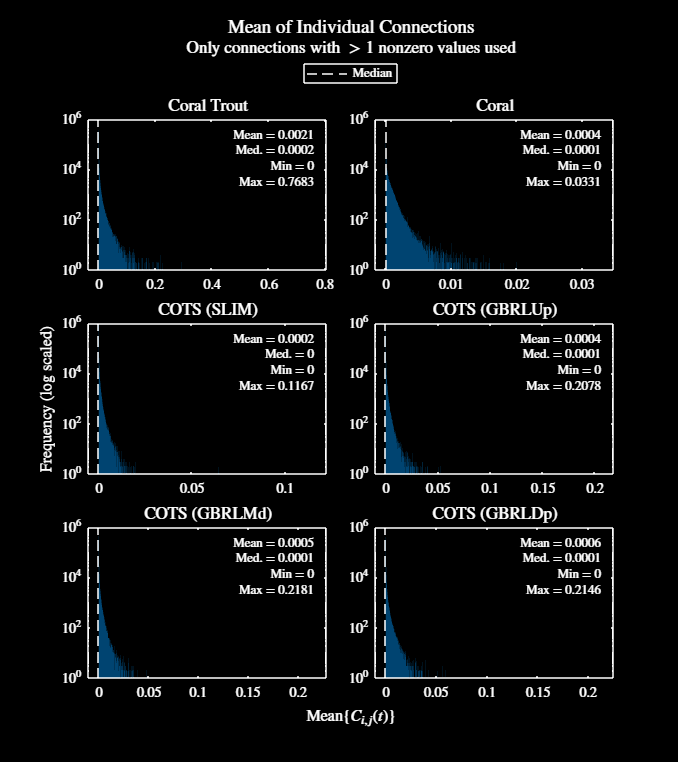

% gonna make a plot function for the connectivity analysis stuff that will
% plot all of the shit at once just like the above for the connectivity
% distributions
figure
plotConnectivityStats({meanConnCT, meanConnHaw, meanConnSLIM, ...
    meanConnGBRLUp, meanConnGBRLMd, meanConnGBRLDp}, "mean", ...
    conAnalysisColNames)
setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityMeans")
darkFig()
saveFig("connectivityMeansDM")

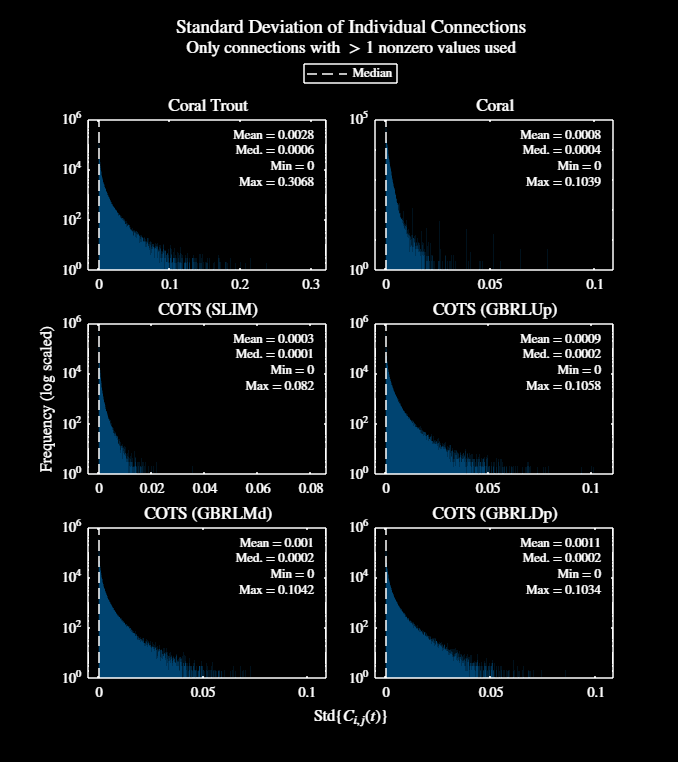

figure
plotConnectivityStats({stdConnCT, stdConnHaw, stdConnSLIM, stdConnGBRLUp, ...
    stdConnGBRLMd, stdConnGBRLDp}, "std", conAnalysisColNames)
setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityStds")
darkFig()
saveFig("connectivityStdsDM")

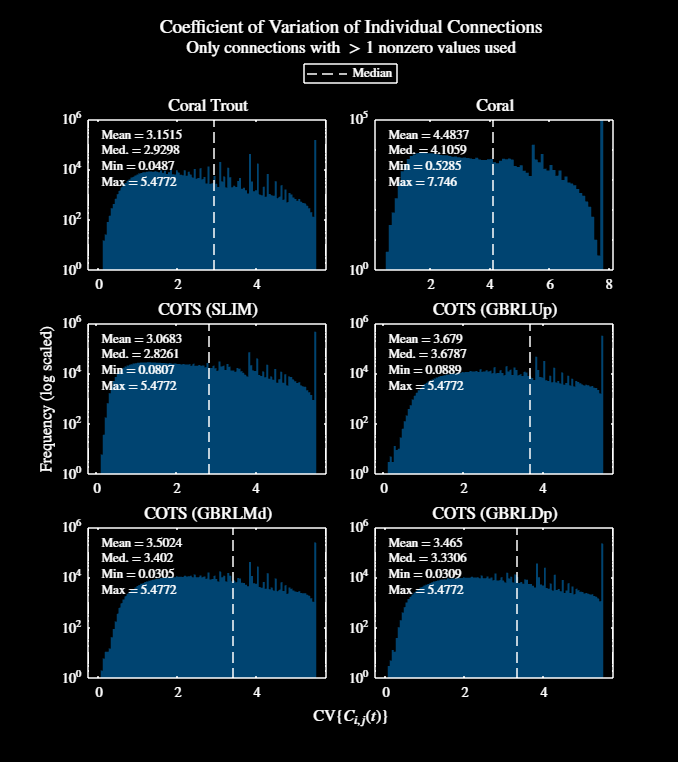

figure
plotConnectivityStats({stdConnCT ./ meanConnCT, stdConnHaw ./ meanConnHaw, ...
    stdConnSLIM ./ meanConnSLIM, stdConnGBRLUp ./ meanConnGBRLUp, ...
    stdConnGBRLMd ./ meanConnGBRLMd, stdConnGBRLDp ./ meanConnGBRLDp}, ...
    "CV", conAnalysisColNames)
setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityCVs")
darkFig()
saveFig("connectivityCVsDM")

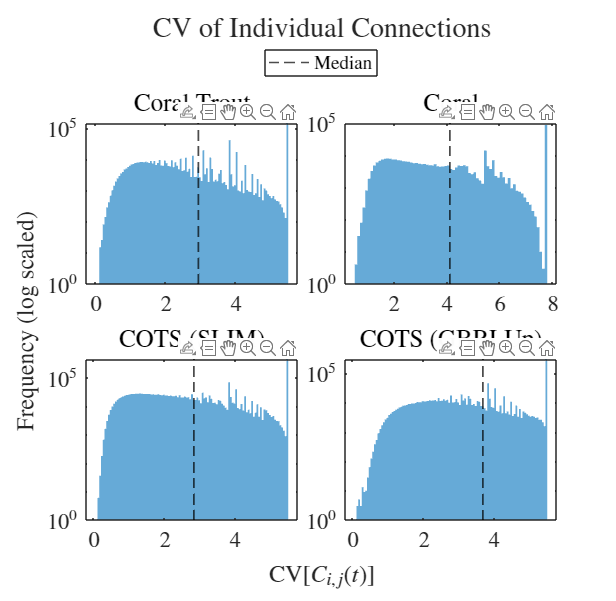

figure
plotConnectivityStats({stdConnCT ./ meanConnCT, stdConnHaw ./ meanConnHaw, ...
    stdConnSLIM ./ meanConnSLIM, stdConnGBRLUp ./ meanConnGBRLUp}, ...
    "CV", conAnalysisColNames(1:4), "pres")
setFontSize(18)
figResize(1.3)
saveFig("connectivityCVsPP")

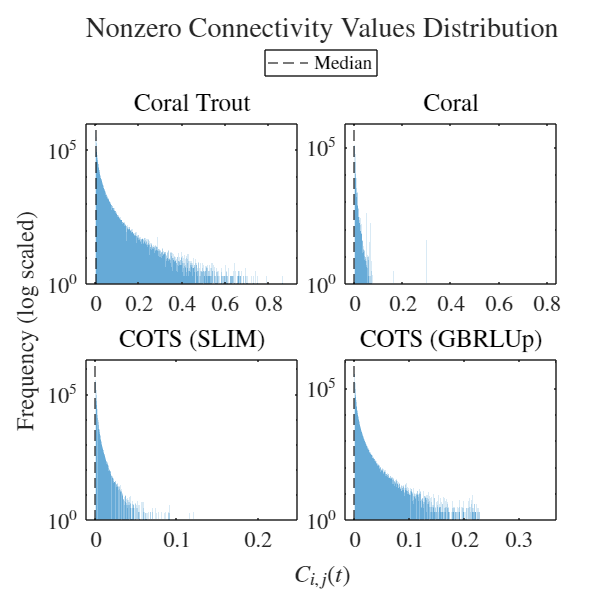

figure
plotConnectivityDist({conMatsCT, conMatsHawaii, conMatsSLIM, ...
    conMatsGBRLUp}, conAnalysisColNames(1:4), "pres")
setFontSize(18)
figResize(1.3)
saveFig("connectivityDistributionPP")

% need to think about what the 5 represents again lmao
var1 = zeros(1, 10);
var1(1) = 1;
std(var1) / mean(var1)

ans = 3.1623

var1 = zeros(1, 30);
var1([1, 2]) = 1;
std(var1) / mean(var1)

ans = 3.8056

var1 = zeros(1, 30);
var1(1) = 1;
std(var1) / mean(var1)

ans = 5.4772

## Data Analysis of Connectivity - Autocorrelation

% calculate the autocorrelations for the coral trout data
ind = [1:5, 7:11, 13:17, 19:23, 25:29];
[autocorrMonthlyCT, ~] = calcAutocorr(conMatsCT, eps, ind); 

% calculate the autocorrelations for the coral data
ind = [];
for i = 1:length(conMatsHawaii)
    if mod(i, 3) ~= 0
        ind = [ind, i];
    end
end
[autocorrMonthlyHawaii, ~] = calcAutocorr(conMatsHawaii, eps, ind);

% calculate the autocorrelations for the SLIM data
ind = [1:9, 10:19, 20:29];
[autocorrWeeklySLIM, ~] = calcAutocorr(conMatsSLIM, eps, ind);

% calculate the autocorrelations for the GBRLUp data
ind = [1:9, 10:19, 20:29];
[autocorrWeeklyGBRLUp, ~] = calcAutocorr(conMatsGBRLUp, eps, ind);

% calculate the autocorrelations for the GBRLMd data
ind = [1:9, 10:19, 20:29];
[autocorrWeeklyGBRLMd, ~] = calcAutocorr(conMatsGBRLMd, eps, ind);

% calculate the autocorrelations for the GBRLDp data
ind = [1:9, 10:19, 20:29];
[autocorrWeeklyGBRLDp, ~] = calcAutocorr(conMatsGBRLDp, eps, ind);

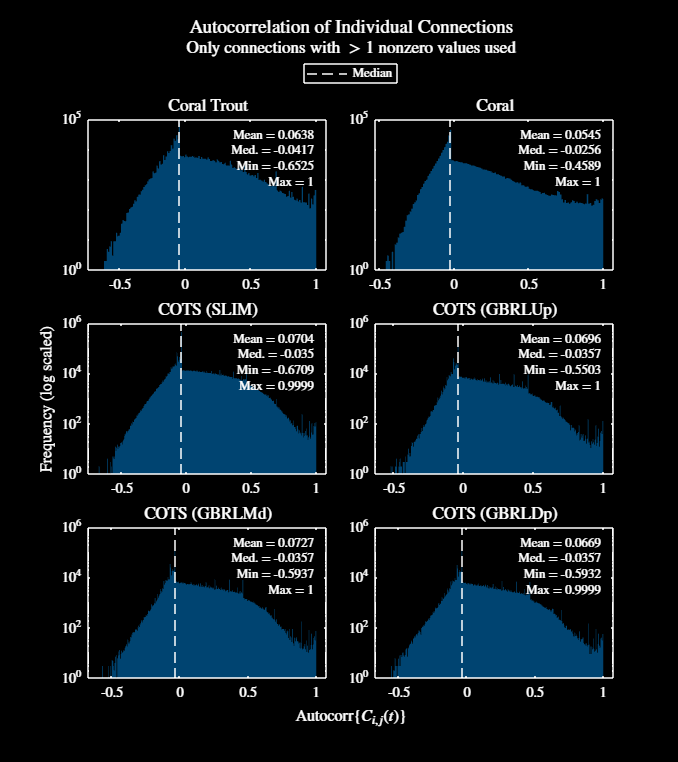

% plot then autocorrelation for everything
figure
plotConnectivityStats({autocorrMonthlyCT, autocorrMonthlyHawaii, ...
    autocorrWeeklySLIM, autocorrWeeklyGBRLUp, autocorrWeeklyGBRLMd ...
    autocorrWeeklyGBRLDp}, "autocorrelation", conAnalysisColNames)
setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityAutocorr")
darkFig()

saveFig("connectivityAutocorrDM")

## Data Analysis of Connectivity - Correlation

% gonna plot correlations based on time series of the row sums for each
% reef heheheeeehe, beginning with the coral trout data
corrMatCT = calcLarvalCorr(conMatsCT); 

% calculate the autocorrelations for the coral data
corrMatHawaii = calcLarvalCorr(conMatsHawaii); 

% calculate the autocorrelations for the SLIM data
corrMatSLIM = calcLarvalCorr(conMatsSLIM); 

% calculate the autocorrelations for the GBRLUp data
corrMatGBRLUp = calcLarvalCorr(conMatsGBRLUp); 

% calculate the autocorrelations for the GBRLMd data
corrMatGBRLMd = calcLarvalCorr(conMatsGBRLMd);

% calculate the autocorrelations for the GBRLDp data
corrMatGBRLDp = calcLarvalCorr(conMatsGBRLDp);

% do a nice big figure of them :)
figure
plotConnectivityStats({corrMatCT(:), corrMatHawaii(:), corrMatSLIM(:), ...
    corrMatGBRLUp(:), corrMatGBRLMd(:), corrMatGBRLDp(:)}, "correlation", ...
    conAnalysisColNames)

Unrecognized function or variable 'corrMatHawaii'.

setFontSize(12)
figResize(1.8, 1.2)
saveFig("connectivityCorr")
darkFig()
saveFig("connectivityCorrDM")

## Data Analysis Main Text Figure - Coral Trout

% do one final figure with all the metrics one by one hehehheeheheheeheeeh
figure
plotConnectivityAnalysis({conMatsCT, meanConnCT, stdConnCT, ...
    autocorrMonthlyCT, corrMatCT}, [], [], eps, "Coral Trout")
saveFig("connectivityAnalysisCoralTrout")
darkFig()
saveFig("connectivityAnalysisCoralTroutDM")

% clear a bunch of these variables so they don't clog up my workspace,
% they're pretty fucked big too
clear meanConnCT stdConnCT minMaxConnCT meanConnSLIM stdConnSLIM ...
    minMaxConnSLIM meanConnGBRLUp stdConnGBRLUp minMaxConnGBRLUp ...
    meanConnGBRLMd stdConnGBRLMd minMaxConnGBRLMd meanConnGBRLDp ...
    stdConnGBRLDp minMaxConnGBRLDp
clear autocorrMonthlyHawaii autocorrMonthlyCT autocorrWeeklySLIM ...
    autocorrWeeklyGBRLUp autocorrWeeklyGBRLMd autocorrWeeklyGBRLDp
clear corrMatCT corrMatHawaii corrMatSLIM corrMatGBRLUp ...
    corrMatGBRLMd corrMatGBRLDp

## Analytical Methods Correlation Plots

% throw out some variables xd
c1Mean = 0.002;
c2Mean = 0.0025;
n1Mean = 90;
n2Mean = 80;
c1Sd = 0.0015;
c2Sd = 0.00175;
n1Sd = 40;
n2Sd = 30;
rSq = 150;

% create vectors of the correlations
corrCVec = linspace(-1, 1, 101);
corrNVec = linspace(-1, 1, 101);

% use a for loop to calc the variances
varS3Mat = zeros(length(corrCVec), length(corrNVec));
for i = 1:length(corrCVec)
    for j = 1:length(corrNVec)
        varS3Mat(i, j) = rSq * (c1Mean^2 * n1Sd^2 + c2Mean^2 * n2Sd^2 ...
            + n1Mean^2 * c1Sd^2 + n2Mean^2 * c2Sd^2 + c1Sd^2 * n1Sd^2 ...
            + c2Sd^2 * n2Sd^2 + 2 * (c1Mean * c2Mean * n1Sd * n2Sd ...
            * corrNVec(j) + n1Mean * n2Mean * c1Sd * c2Sd * corrCVec(i) ...
            + c1Sd * c2Sd * n1Sd * n2Sd * corrCVec(i) * corrNVec(j)));
    end
end

% now plot the results
figure
imagesc(corrCVec, corrNVec, varS3Mat)
set(gca, "Ydir", "normal")
colormap(myColourMap())
colorbar
darkFig()

% let's do the same, but make the standard devs bigger than the mean values
c1Sd = 0.0035;
c2Sd = 0.0035;
n1Sd = 110;
n2Sd = 105;

% use a for loop to calc the variances
varS3Mat = zeros(length(corrCVec), length(corrNVec));
for i = 1:length(corrCVec)
    for j = 1:length(corrNVec)
        varS3Mat(i, j) = rSq * (c1Mean^2 * n1Sd^2 + c2Mean^2 * n2Sd^2 ...
            + n1Mean^2 * c1Sd^2 + n2Mean^2 * c2Sd^2 + c1Sd^2 * n1Sd^2 ...
            + c2Sd^2 * n2Sd^2 + 2 * (c1Mean * c2Mean * n1Sd * n2Sd ...
            * corrNVec(j) + n1Mean * n2Mean * c1Sd * c2Sd * corrCVec(i) ...
            + c1Sd * c2Sd * n1Sd * n2Sd * corrCVec(i) * corrNVec(j)));
    end
end

% now plot the results
figure
imagesc(corrCVec, corrNVec, varS3Mat)
set(gca, "Ydir", "normal")
colormap(myColourMap())
colorbar
darkFig()

% let's do the same, but make the standard devs bigger than the mean values
c1Sd = 0.0015;
c2Sd = 0.00175;
n1Sd = 110;
n2Sd = 105;

% use a for loop to calc the variances
varS3Mat = zeros(length(corrCVec), length(corrNVec));
for i = 1:length(corrCVec)
    for j = 1:length(corrNVec)
        varS3Mat(i, j) = rSq * (c1Mean^2 * n1Sd^2 + c2Mean^2 * n2Sd^2 ...
            + n1Mean^2 * c1Sd^2 + n2Mean^2 * c2Sd^2 + c1Sd^2 * n1Sd^2 ...
            + c2Sd^2 * n2Sd^2 + 2 * (c1Mean * c2Mean * n1Sd * n2Sd ...
            * corrNVec(j) + n1Mean * n2Mean * c1Sd * c2Sd * corrCVec(i) ...
            + c1Sd * c2Sd * n1Sd * n2Sd * corrCVec(i) * corrNVec(j)));
    end
end

% now plot the results
figure
imagesc(corrCVec, corrNVec, varS3Mat)
set(gca, "Ydir", "normal")
colormap(myColourMap())
colorbar
darkFig()

figure
plot(0, 0)
darkFig()

% let's do a surface 3d plot of these so I can see what the hell is going
% onsetFontSize(14)
[var1 ,var2] = meshgrid(corrCVec, corrNVec);
figure
surf(var1, var2, varS3Mat)
darkFig()

## Solution Characteristics

% let's first look at the proportional overlaps

% note that I'm going to remove the random portfolios here, don't think it
% would be all that useful
figure
plotOverlapProps(simOutCellSwains(3:end), [], "Swains")
darkFig()
figure
plotOverlapProps(simOutCellTowns(3:end), [], "Townsville")
darkFig()
figure
plotOverlapProps(simOutCellNorth(3:end), [], "North")
darkFig()

% let's look at the number of reefs selected
figure
plotNumReefs(simOutCellSwains, "Swains", false)
setFontSize(12)
saveFig("numReefsChosenSwains")
plotNumReefs(simOutCellSwains, "Swains", true)
darkFig()
setFontSize(12)
saveFig("numReefsChosenSwainsDM")

figure
plotNumReefs(simOutCellTowns, "Towns", false)
setFontSize(12)
saveFig("numReefsChosenTowns")
plotNumReefs(simOutCellTowns, "Towns", true)
darkFig()
setFontSize(12)
saveFig("numReefsChosenTownsDM")

figure
plotNumReefs(simOutCellNorth, "North", false)
setFontSize(12)
saveFig("numReefsChosenNorth")
plotNumReefs(simOutCellNorth, "North", true)
darkFig()
setFontSize(12)
saveFig("numReefsChosenNorthDM")

simOutCellTowns{1}.mpaSel{1}

% now, let's look at the proportional overlaps inside the models methinks

## 3 Reef Analytical Model Optimisation Space

% let's do some figures here - epic mode

% gonna write this into a function because I'm a beta soyboy loser

% here's a figure for the 
figure
tL = tiledlayout(3, 2, "TileSpacing", "tight");

% do a case for both CVs are less than 1
nexttile
plot3ReefOptSpace(0.007, 0.008, 0.003, 0.002, 100, 120, 20, 30)

ans =     -1    -1



% do a case CVc > CVn
nexttile
plot3ReefOptSpace(0.003, 0.002, 0.009, 0.008, 80, 100, 100, 120)

ans =     -1     1



% do a case CVc < CVn
nexttile
plot3ReefOptSpace(0.003, 0.002, 0.001, 0.005, 90, 80, 100, 120)

ans =      1    -1



% do a case CVc > CVn but CVc == 1
nexttile
plot3ReefOptSpace(0.003, 0.002, 0.003, 0.002, 80, 100, 70, 80)

ans =    -1.0000   -0.9400



% do a case CVc < CVn but CVn == 1
nexttile
plot3ReefOptSpace(0.003, 0.002, 0.001, 0.0008, 90, 80, 90, 80)

ans =     -1    -1



% do a case for both CVs equal to 1
nexttile
plot3ReefOptSpace(0.007, 0.008, 0.007, 0.008, 70, 80, 70, 80)

ans =    -0.9600   -1.0000


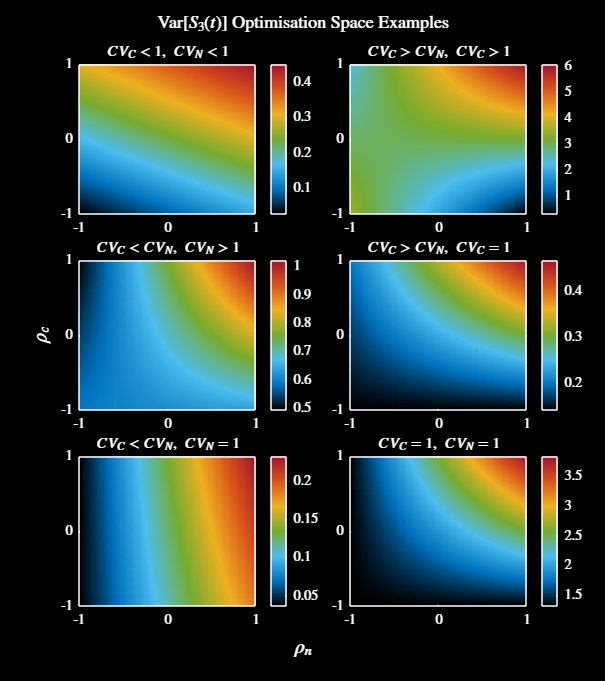


% use global labels
setFontSize(11.5)
title(tL, "Var$[S_3(t)]$ Optimisation Space Examples", ...
    'interpreter', 'latex')
xlabel(tL, "$\rho_n$", 'Interpreter', 'Latex', 'FontSize', 15)
ylabel(tL, "$\rho_c$", 'Interpreter', 'Latex', 'FontSize', 15)
figResize(1.5)

% save stuff
lightFig()
saveFig("connPopVarSurf")
darkFig()
saveFig("connPopVarSurfDM")

% plot some shit
figure
plot3ReefOptSpace(0.003, 0.002, 0.007, 0.008, 50, 30, 100, 120)
darkFig()

% plot some shit
figure
plot3ReefOptSpace(0.007, 0.008, 0.007, 0.008, 100, 120, 100, 120)
darkFig()

figure
plot(0, 1)
darkFig()

## Analytical Example Numerical Simulations

% write this shit as a function
sim3ReefSystem()

## Real Correlation Figures

% gonna make some fun little figures of reefs here, first setting the reefs
% coordinates
reefX = [1, 2, 3];
reefY = [0, 0, 0];
nReefs = length(reefX);

% setup the figure
figure
tiledlayout(2, 1, "TileSpacing", "compact")
nexttile
hold on
nodeSize = 90;
labelSize = 15;

% plot some sine waves to demonstrate oceanographic flow
sinX = linspace(0.5, 3.5, 101);
indMarker = 1:10:101;
sinY = 0.035 * sin(20 * sinX / pi);
plot(sinX, sinY + 0.25, 'k')
plot(sinX(indMarker), sinY(indMarker) + 0.25, 'k<', 'MarkerFaceColor', 'k')
plot(sinX, sinY + 0.125, 'k')
plot(sinX(indMarker), sinY(indMarker) + 0.125, 'k<', 'MarkerFaceColor', 'k')
plot(sinX, sinY, 'k')
plot(sinX(indMarker), sinY(indMarker), 'k<', 'MarkerFaceColor', 'k')
plot(sinX, sinY - 0.125, 'k')
plot(sinX(indMarker), sinY(indMarker) - 0.125, 'k<', 'MarkerFaceColor', 'k')
plot(sinX, sinY - 0.25, 'k')
plot(sinX(indMarker), sinY(indMarker) - 0.25, 'k<', 'MarkerFaceColor', 'k')

% now draw in circles for the reefs
strVec = ["A", "B", "C"];
for r = 1:nReefs
    plot(reefX(r), reefY(r), 'k.', 'MarkerSize', 1.05 * nodeSize)
    plot(reefX(r), reefY(r), '.', 'MarkerSize', nodeSize, 'Color', ...
        getColour(r, nReefs))
    text(reefX(r), reefY(r), strVec(r), "FontSize", labelSize, ...
        'Color', 'w', 'FontWeight', 'bold', 'lineStyle', 'none', ...
        'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle')
end

% turn the axes off and set a title
title("Scenario 1", 'FontSize', 14)
axis off

% plot some sine waves to demonstrate oceanographic flow
nexttile
hold on
plot(sinX, sinY + 0.25, 'k')
plot(sinX(indMarker), sinY(indMarker) + 0.25, 'k>', 'MarkerFaceColor', 'k')
plot(sinX, sinY + 0.125, 'k')
plot(sinX(indMarker), sinY(indMarker) + 0.125, 'k>', 'MarkerFaceColor', 'k')
plot(sinX, sinY, 'k')
plot(sinX(indMarker), sinY(indMarker), 'k>', 'MarkerFaceColor', 'k')
plot(sinX, sinY - 0.125, 'k')
plot(sinX(indMarker), sinY(indMarker) - 0.125, 'k>', 'MarkerFaceColor', 'k')
plot(sinX, sinY - 0.25, 'k')
plot(sinX(indMarker), sinY(indMarker) - 0.25, 'k>', 'MarkerFaceColor', 'k')

% now draw in circles for the reefs
for r = 1:nReefs
    plot(reefX(r), reefY(r), 'k.', 'MarkerSize', 1.05 * nodeSize)
    plot(reefX(r), reefY(r), '.', 'MarkerSize', nodeSize, 'Color', ...
        getColour(r, nReefs))
    text(reefX(r), reefY(r), strVec(r), "FontSize", labelSize, ...
        'Color', 'w', 'FontWeight', 'bold', 'lineStyle', 'none', ...
        'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle')
end

% throw down a title and turn off the axes
title("Scenario 2", 'FontSize', 14)
axis off

% manage figure
figResize(0.75)
saveFig("connectivityCorrExample")
darkFig()
saveFig("connectivityCorrExampleDM")

## Coral Trout Figure

% need to create a figure of the main metrics for coral trout - just the
% distribution of the individual connections, and settlement probabilities
% along with their coefficient of variation

% need to first grab all the nonzero values
currData = [];
numNonzero = 0;
for i = 1:length(conMatsCT)
    currData = [currData; double(conMatsCT{i}(:))];
    currData = currData(currData > 0);
    numNonzero = numNonzero + sum(sum(conMatsCT{i} > 0));
end
nonzeroProp = numNonzero / (size(conMatsCT{1}, 1)^2 * length(conMatsCT));

% need to also grab he settlement probabilities
settlementProbCT = [];
for i = 1:length(conMatsCT)
    settlementProbCT = [settlementProbCT; sum(conMatsCT{i}, 2)];
end

% need to calculate the CV of the settlement probabilities
settProbMat = zeros(size(conMatsCT{1}, 2), length(conMatsCT));
for i = 1:length(conMatsCT)
    settProbMat(:, i) = sum(conMatsCT{i}, 2);
end

% now calculate the means
meanSettProb = mean(settProbMat, 2);
stdSettProb = std(settProbMat, [], 2);

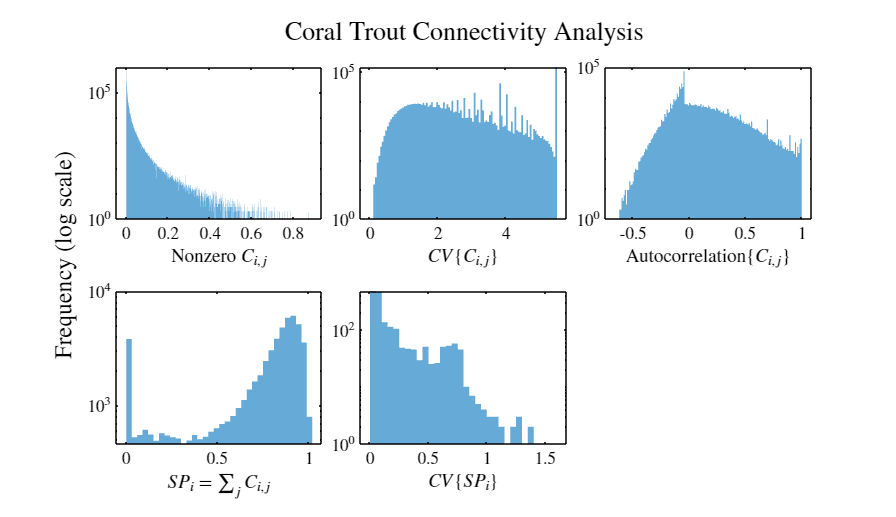

% after that, will do their autocorrelation
figure
tL = tiledlayout(2, 3, 'TileSpacing', 'compact');
nexttile
histogram(currData, "EdgeAlpha", 0, "FaceColor", ...
    getColour('b'))
set(gca, 'YScale', 'log')
xlabel("Nonzero $C_{i, j}$")
nexttile
histogram(stdConnCT ./ meanConnCT, "EdgeAlpha", 0, "FaceColor", ...
    getColour('b'))
set(gca, 'YScale', 'log')
xlabel("$CV\{C_{i, j}\}$")
nexttile
histogram(autocorrMonthlyCT, "EdgeAlpha", 0, "FaceColor", ...
    getColour('b'))
xlabel("Autocorrelation$\{C_{i, j}\}$")
set(gca, 'YScale', 'log')
nexttile
histogram(settlementProbCT, "EdgeAlpha", 0, "FaceColor", ...
    getColour('b'))
xlabel("$SP_i = \sum_j C_{i, j}$")
set(gca, 'YScale', 'log')
nexttile
histogram(stdSettProb ./ meanSettProb, "EdgeAlpha", 0, "FaceColor", ...
    getColour('b'))
xlabel("$CV\{ SP_i \}$")
set(gca, 'YScale', 'log')
figResize(1, 1.3)
ylabel(tL, "Frequency (log scale)", 'interpreter', 'latex')
title(tL, "Coral Trout Connectivity Analysis", 'Interpreter', 'latex')
darkFig()
saveFig("coralTroutConnAnalysisDM")
lightFig()
saveFig("coralTroutConnAnalysis")